## **Question 1**

[filepath,name,ext] = fileparts(which('live_demo'));
filepath_model = strjoin({filepath,'tutorial.inp'},'\');

mdl = swmm(filepath_model);
disp(mdl.p.subcatchments)

     Name     RainGage     Outlet    Area    PercentImperv    Width    PercentSlope    CurbLen     Snowpack 
    ______    _________    ______    ____    _____________    _____    ____________    _______    __________

    {'S1'}    {'Gage1'}    {'J1'}     4           50           400         0.5            0       {0×0 char}
    {'S2'}    {'Gage1'}    {'J2'}     4           50           400         0.5            0       {0×0 char}
    {'S3'}    {'Gage1'}    {'J3'}     4           25           400         0.5            0       {0×0 char}



disp(mdl.p.conduits)

     Name     FromNode     ToNode     Length    Roughness    InOffset    OutOffset    InitFlow    MaxFlow
    ______    ________    ________    ______    _________    ________    _________    ________    _______

    {'C1'}     {'J1'}     {'J2'  }     400        0.01          0            0           0           0   
    {'C2'}     {'J2'}     {'J4'  }     400        0.01          0            0           0           0   
    {'C3'}     {'J3'}     {'J4'  }     400        0.01          0            0           0           0   
    {'C4'}     {'J4'}     {'Out1'}     400        0.01          0            0           0           0   



% only report the outfall (saves write time)
out_name = char(mdl.p.outfalls.Name);
mdl.p.report.NODES = {out_name};
mdl.p.report.SUBCATCHMENTS = {'NONE'};
mdl.p.report.LINKS = {'NONE'};

% change the percent imperviousness of subcatchment 'S1'
mdl.p.subcatchments{ismember('S1',mdl.p.subcatchments.Name),'PercentImperv'} = 75;

% run the simulation
mdl.runsim;

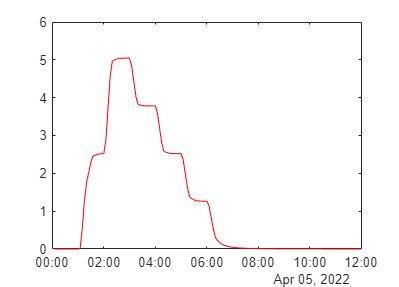


% run simulation
tt_outfl = mdl.results_tt(out_name);

figure('Name','outflow_hydrograph');
plot(tt_outfl.Properties.RowTimes,tt_outfl{:,"inflow"},'-',"Color",'red');

ylabel('flow [cms]')
